**Ercihan Kara - 2375160**

**Eren Kurkut - 2166882**

## Term Project Part 1

Necessary section where fundamental of the project are built for the subsequent parts!

**Listen to the signal and analyze it:**

% listen the signal using autorecorder:
% audiorecorder creates and returns an audiorecorder object with specified properties

% get the frequency of the original chirp to create reference signal
user_int_freq = {'frequency start (Hz):', 'frequency end (Hz):'};
title_inp = 'Type the start and end frequencies of the original signal';
dims = [1 80];
defalut_input = {'0', '0'};
freq_input = inputdlg(user_int_freq, title_inp, dims, defalut_input);

samp_rate = 1e+04; % 10000 default, not user-defined, but built-in
bits = 8; % default
channels = 1; % default
ID = -1; % default
start_freq = str2double(freq_input(1));
end_freq = str2double(freq_input(2));

% object created
obj = audiorecorder(samp_rate, bits, channels, ID);
% start recording using the object
record(obj);

% wait for a key press to stop the recording
disp('press any key to stop recording!');
waitforbuttonpress;

% stop recording and get the recorded data
stop(obj);
data = getaudiodata(obj);

% save the sound data
sound = getaudiodata(obj, 'double');

% amplify the signal by the constant determine by testing the test
% environment
sound = 10 * sound;

% play it to check
play(obj);

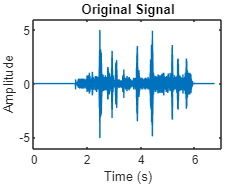

% plot in time domain

t = (0:length(sound)-1)/samp_rate;  % Time vector

figure;
plot(t, sound);
xlabel('Time (s)');
ylabel('Amplitude');
title('Original Signal');

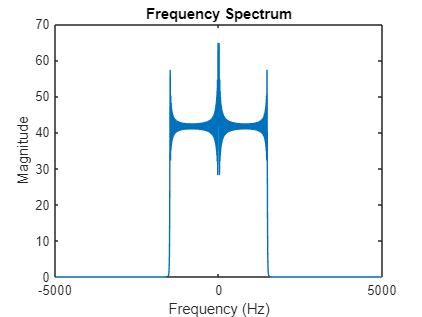

% plot in frequency domain using fft

filteredSoundData = sound;
N = length(filteredSoundData);
frequencies = (0:N-1)*(samp_rate/N);  % Frequency vector
signalFFT = fftshift(fft(filteredSoundData'));
fshift = ((-N/2):(N/2)-1)*samp_rate/N;
amplitudeSpectrum = abs(signalFFT).^2/N;

% % find the frequency with the maximum magnitude
% [~, maxIndex] = max(amplitudeSpectrum);
% maxFrequency = frequencies(maxIndex);
% 
% % the estimation for the max frequency of the incoming chirp
% max_freq_est1 = ((length(frequencies)-1)/2 - maxIndex)/((length(frequencies)-1)/samp_rate);

figure;
plot(fshift, amplitudeSpectrum);
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Frequency Spectrum');

% MF application for the detection of an incoming chirp signal and duration
% estimation

% generate a set of chirp signals with different frequency sweeps and durations
Fs = 1e+04; % sampling rate in Hz
duras = 1:1:20; % duration of the chirp signals in seconds
fstart = start_freq; % start frequency of the chirp signals in Hz
fend = end_freq; % end frequency of the chirp signals in Hz
numChirps = length(duras); % number of chirp signals to generate
chirpSet = cell(numChirps, 1);
for i = 1:numChirps
    t = linspace(0, duras(i), Fs*duras(i));
    f = linspace(fstart, fend, length(t));
    chirpSet{i} = chirp(t, f(1), duras(i), f(end));
end

% create a set of matched filters that correspond to the generated chirp signals
matchedFilters = cell(numChirps, 1);
for i = 1:numChirps
    matchedFilters{i} = conj(fliplr(chirpSet{i}));
end
filteredSoundData = sound;
% convolve the input signal with each of the matched filters in the set
inputSignal = filteredSoundData;
correlationOutputs = zeros(numChirps, length(inputSignal));
for i = 1:numChirps
    correlationOutputs(i,:) = conv(inputSignal, matchedFilters{i}, 'same');
end

for i = 1:numChirps
    max_arr(i) = max(correlationOutputs(i,:));
end
[max_val, max_ind] = max(max_arr);
% analyze the correlation outputs to determine which one corresponds to the highest correlation
[maxCorrelation, maxIndex] = max(abs(correlationOutputs), [], 1);

% determine a threshold for the correlation output to classify the input as a chirp signal or not
threshold = 2000;
maxer = max(maxCorrelation);

% classify the input as a chirp signal or not; if chirp continue, else
% finish the program
if max(maxCorrelation) > threshold
    disp(['The input signal is a chirp signal with duration of ', num2str(duras(max_ind)), ' seconds']);
else
    disp('The input signal is not a chirp signal, quitting the program!');
    %quit
end

The input signal is not a chirp signal, quitting the program!



duration_est = duras(max_ind);

% MF application for the detection of an incoming chirp signal and
% frequency estimation

% generate a set of chirp signals with different frequency sweeps and durations
Fs = 1e+04; % sampling rate in Hz
dura_det = duration_est; % duration of the chirp signals in seconds

fstart = 0:200:2000; % start frequency of the chirp signals in Hz
fend = 2000:200:4000; % end frequency of the chirp signals in Hz
numChirps = length(fstart) * length(fend); % number of chirp signals to generate

chirpSet = cell(numChirps, 1);
freq_set = cell(numChirps, 1);
k = 1;
for j = 1:length(fstart)
    for i = 1:length(fend)
        t = linspace(0, dura_det, Fs*dura_det);
        %f = linspace(fstart(j), fend(i), length(t));
        chirpSet{k} = chirp(t, fstart(j), dura_det, fend(i));
        freq_set{k} = [fstart(j) fend(i)];
        k = k + 1;
    end
end

% create a set of matched filters that correspond to the generated chirp signals
matchedFilters = cell(numChirps, 1);
for i = 1:numChirps
    matchedFilters{i} = conj(fliplr(chirpSet{i}));
end
filteredSoundData = sound(1:end-1);
% convolve the input signal with each of the matched filters in the set
inputSignal = filteredSoundData;
correlationOutputs = zeros(numChirps, length(inputSignal));
for i = 1:numChirps
    correlationOutputs(i,:) = conv(inputSignal, matchedFilters{i}, 'same');
end

for i = 1:numChirps
    max_arr(i) = max(correlationOutputs(i,:));
end
[max_val_freq, max_ind_freq] = max(max_arr);
% analyze the correlation outputs to determine which one corresponds to the highest correlation
[maxCorrelation_freq, maxIndex_freq] = max(abs(correlationOutputs), [], 1);
max(maxCorrelation_freq);
% frequency estimation
freqs = freq_set{max_ind_freq};

% frequency, amplitude, rate of frequency increase and bandwidth estimation

% while creating the sound signal, the incoming data is amplified by a
% constant. thus, checking the max value gives a near value to the original
% amplitude. however, exact value cannot be reached due to the transmission
% of the created signal from one device to another
ampl_est = max(abs(filteredSoundData));
disp(['amplitude estimation: ', num2str(ampl_est)]);

amplitude estimation: 5



disp(['start frequency estimation: ', num2str(freqs(1))]);

start frequency estimation: 0


disp(['end frequency estimation: ', num2str(freqs(2))]);

end frequency estimation: 2400



bandwidth_est = freqs(2)-freqs(1);
disp(['bandwidth estimation: ', num2str(bandwidth_est)]);

bandwidth estimation: 2400



rate_freq = (bandwidth_est)/duration_est;
disp(['rate of frequency increase estimation: ', num2str(rate_freq)]);

rate of frequency increase estimation: 2400


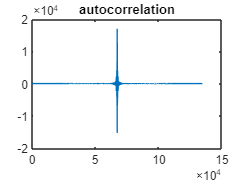

start frequency estimation: 1800


end frequency estimation: 3000


% periodicity estimation using autocorrelation
% EXPLANATION IN REPORT
plot(xcorr(chirpp));
title("autocorrelation")